# 对去畸变后的图像建筑物"竖直倾斜"的直线进行矫正

崔星星 2023.5.23

Email: cuixingxing150@gmail.com

本示例展示了如何**对去畸变后的图像竖直的建筑物“倾斜”进行矫正，以便得到正常视角的“竖直”建筑物。** 用前视环视镜头图像为例，对原始普通广角/超广角/鱼眼畸变图像先进行常规去畸变矫正，**经矫正后（无论是常规棋盘网格标定矫正、厂家畸变表矫正、畸变除法模型利用图像中直线特征矫正）均发现建筑物竖直方向上发生了倾斜**，但仍然保持直线不变性特征，造成此现象的主要原因在于前视环视镜头有一定的俯视角度向地面倾斜拍摄导致，并非摄像头正对前方(光轴垂直于汽车正前方墙面)拍摄，另外也存在镜头在其他2个轴的略微角度倾斜拍摄。

分析到原因，为进行矫正验证，本质上是求一单应矩阵(投影透视变换矩阵)$H$，使得相机光轴从俯视倾斜角度$\alpha$变换为0的虚拟相机拍摄。为单纯矫正图像，一般有两种方法可以做到，**直接法**：直接从空间上表现竖直平行的两条直线在图像上有夹角，从这2条夹角直线上任取一梯形四个顶点到一正规矩形四个顶点求取单应矩阵$H$；**间接法**：从已知相机内参$K$、外参$[R_{3\times3},T_{3\times1}]$等条件下分解单应矩阵$H$依赖这些参数求解。下面给出间接法的推导，后续矫正代码依赖此公式。

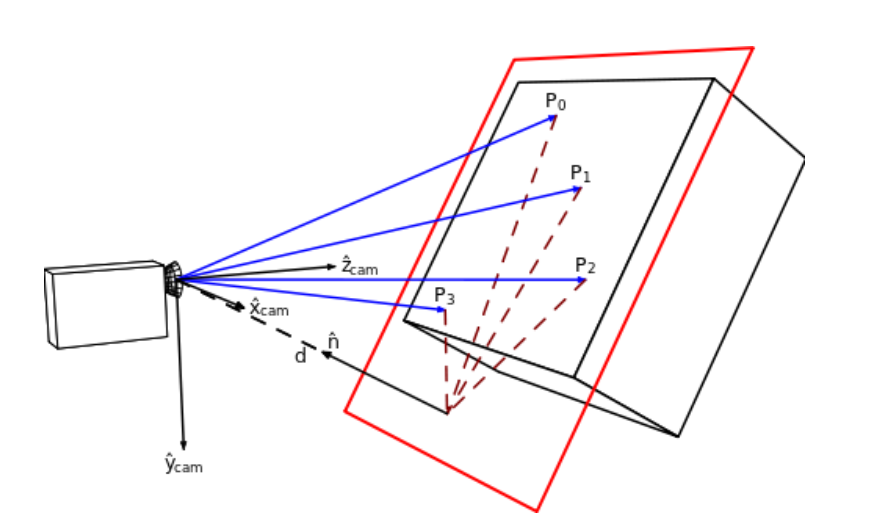

示意图

三维空间上点$P_j =R\;P_i +t$有此转换关系，另平面方程有$n^T P_i +d=0$,则$d=-n^T P_i$，因此$P_j =R\;P_i +1\cdot t=R\;P_i +\left(-\frac{n^T P_i }{d}\right)\cdot t=\left(R-\frac{n^T t}{d}\right)P_i$，又$p_j =Hp_i$，${K^{-1} P}_j =p_j ,{K^{-1} P}_i =p_i$，故$H=K\left(R-\frac{n^T t}{d}\right)K^{-1}$，其中$n$为投影平面的单位法矢量，$K$为相机内参，$d$为光心到投影平面距离，$R$为相对旋转矩阵，$t$为相对平移向量。

下面代码钟使用的“birdsEye360.mat”数据来源于[Visual-Based-Odometry-Estimation/fisheyeCameraCalibration.pdf at main · cuixing158/Visual-Based-Odometry-Estimation (github.com)](https://github.com/cuixing158/Visual-Based-Odometry-Estimation/blob/main/fisheyeCameraCalibration.pdf)，数据下载地址为：

[https://github.com/cuixing158/Visual-Based-Odometry-Estimation/blob/main/data/preSavedData/birdsEye360.mat](https://github.com/cuixing158/Visual-Based-Odometry-Estimation/blob/main/data/preSavedData/birdsEye360.mat) ，主要用了去畸变的映射矩阵mapX,mapY对图像去畸变和车载相机外参，这不是本文重点，故不再展开，有需要了解的可移步上面链接。

load ./birdsEye360.mat 

## step1:直接去畸变

本步骤不是本文主要关注点，故直接采用之前映射坐标关系直接去畸变即可。

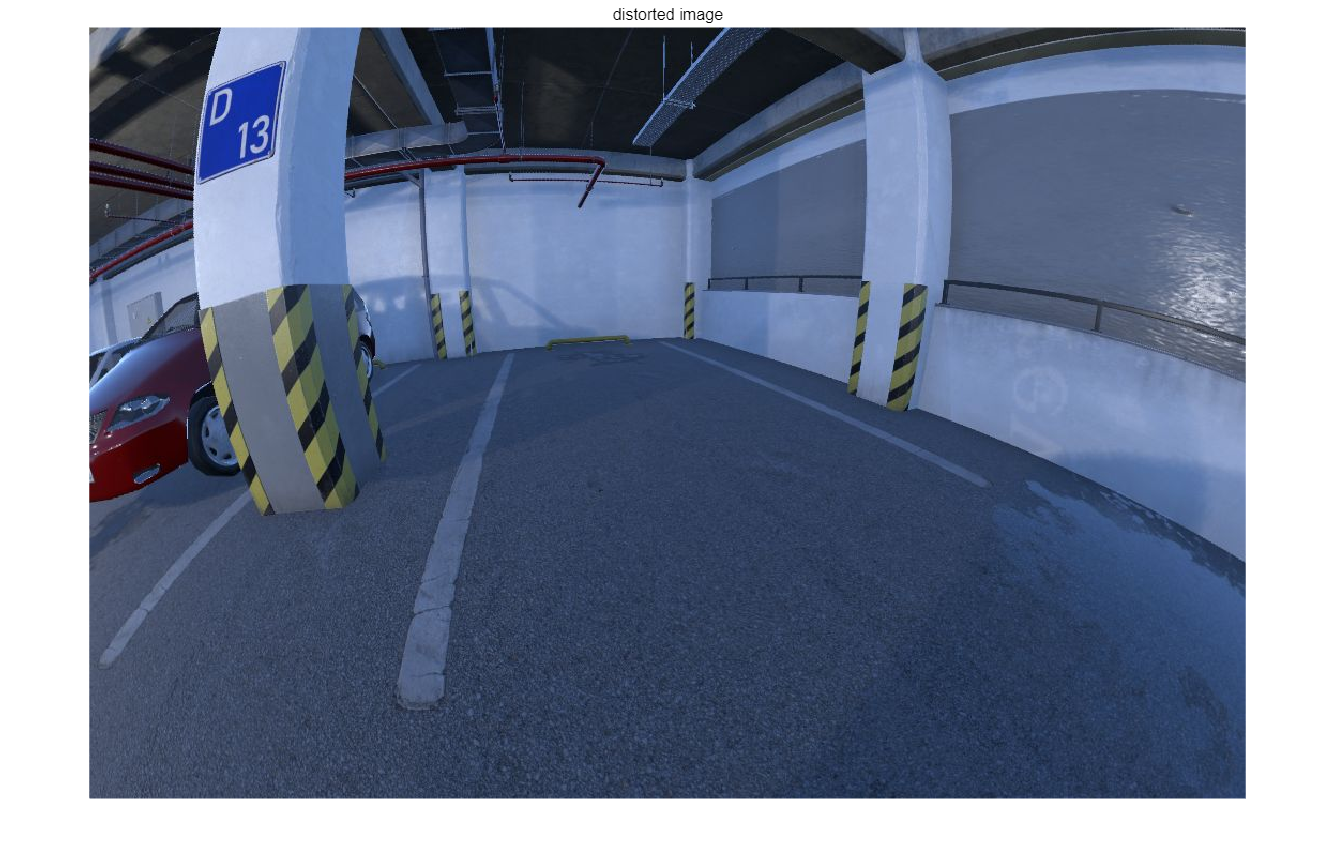

distortedImage = imread("images/1132.jpg");% 典型一张图像
imshow(distortedImage);title("distorted image")

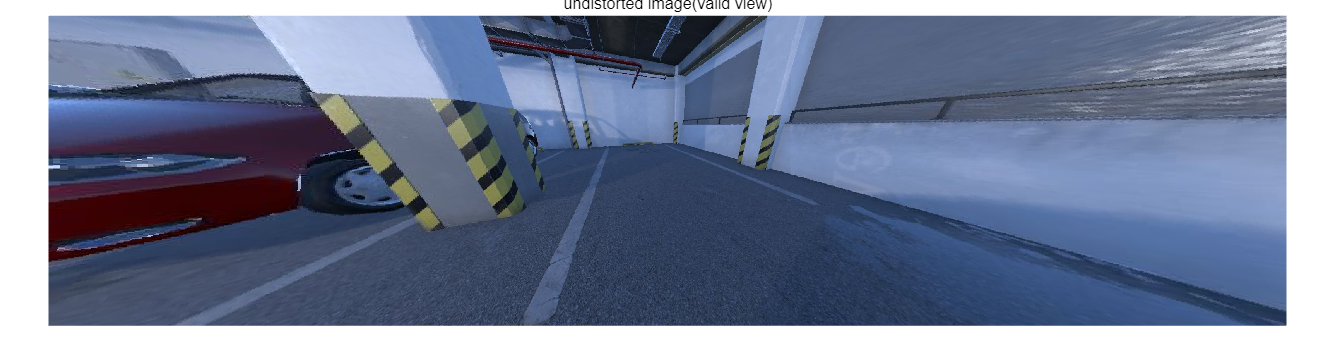

undistortedImg = images.internal.interp2d(distortedImage,mapX,mapY,"linear",0, false);
imshow(undistortedImg);title("undistorted image(valid view)")

此图像为去畸变后的效果，这种图像有点引起“视觉上反常”，就类似于我们人眼略微低头向下看，符合“近大远小”现象。但到此步骤后其实已经可以正常的进行后续其他视觉任务，比如vSLAM，SFM，BEV图像生成，三维重建等都可基于此类图像，当然也可以选择使用下面步骤2或者3后的图像。

## step2:建筑物"倾斜"矫正，本质是求单应(透视变换)矩阵H

导入的变量birdsEye保存的是[birdsEyeView对象](https://ww2.mathworks.cn/help/driving/ref/birdseyeview.html)，本质上就是个保存相机内外参和一些鸟瞰图预定义超参的结构体，方便做鸟瞰图投影罢了，这里关注点我们暂时用不到，我们只取用上述公式所需要的内外参即可，外参是通过相机(sensor)的Pitch，Yaw，Roll给出的，为了换算成**相机物理坐标系**的三个轴的角度对应关系，需要好好对应理解一下。

- 车辆相机(sensor)：

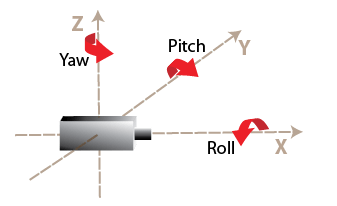

- 相机物理坐标系：

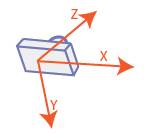

更详细请参阅：[https://ww2.mathworks.cn/help/driving/ug/coordinate-systems.html](https://ww2.mathworks.cn/help/driving/ug/coordinate-systems.html)

intrinsicK = birdsEye{1}.Sensor.Intrinsics;
% 此处需要好好理解，在汽车坐标系看来,三个角度ptich,yaw,roll与相机物理坐标系的对应关系
cameraX = -birdsEye{1}.Sensor.Pitch;
cameraY = -birdsEye{1}.Sensor.Yaw;
cameraZ = birdsEye{1}.Sensor.Roll;
relR = eul2rotm(deg2rad([cameraZ,cameraY,cameraX]),"ZYX");% 三个轴的欧拉角转换为旋转矩阵
relT = zeros(3,1);
normN = [0,0,1]';% 单位法矢量
d = intrinsicK.FocalLength(1);

取用完所需要的参数后，调用上述公式直接求取$H$，代码如下，注意此处只有旋转，没有平移，故相对平移矩阵relT为0。

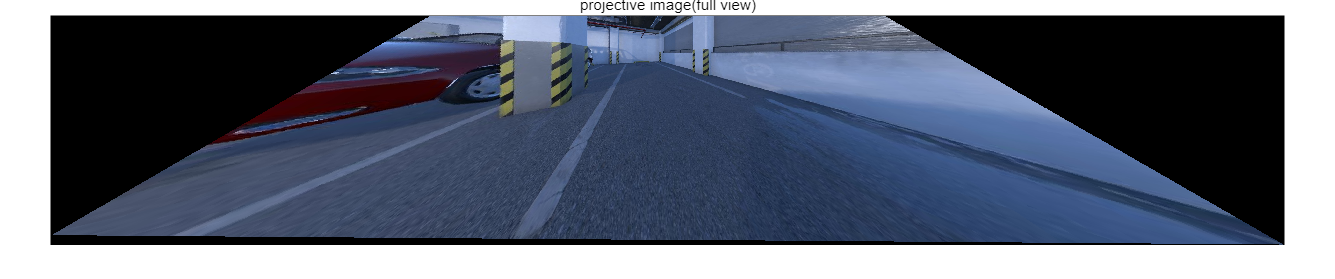

H = projtform2dFromDecompose(intrinsicK,relR,relT,normN,d);
tform = projtform2d(H);

undistortedImg2 = imwarp(undistortedImg,tform);
imshow(undistortedImg2);title("projective image(full view)")

## step3:图像只保留中间有效可视范围

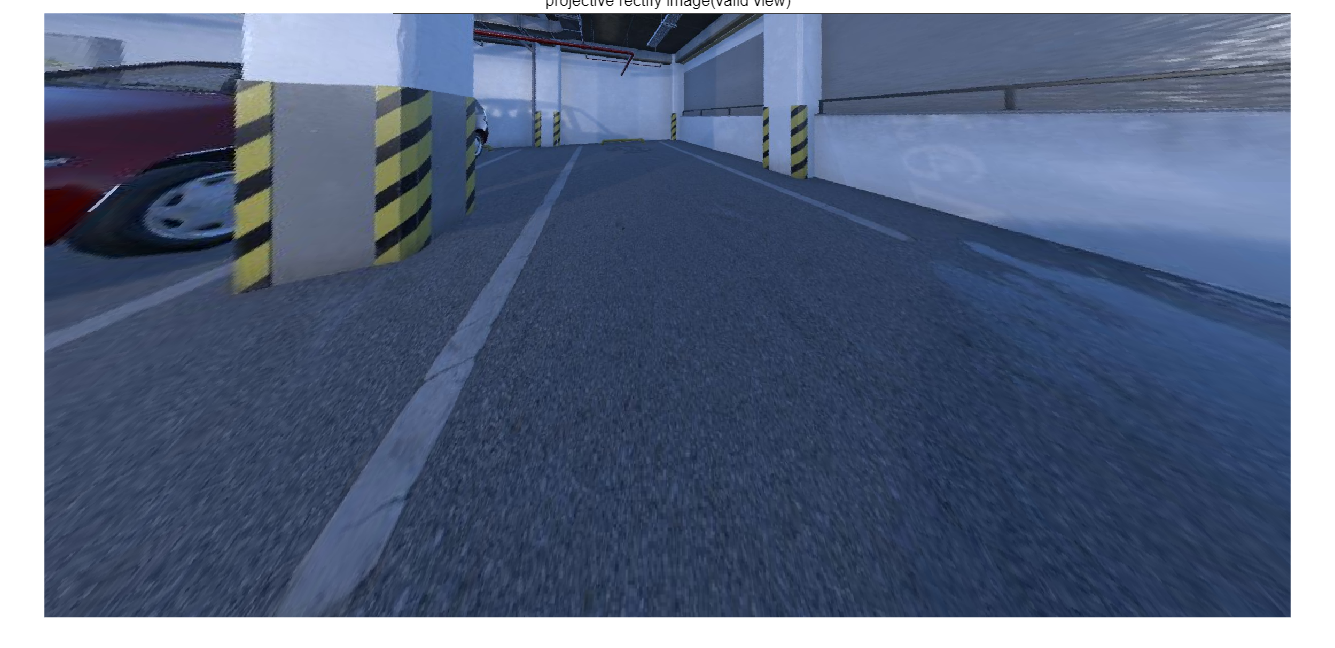

[h,w,~] = size(undistortedImg);
pointsIn = [1,1;
    w,1;
    w,h;
    1,h];
pointsOut = transformPointsForward(tform,pointsIn);
outputH = round(pointsOut(4,2)-pointsOut(1,2));
outputW = round(pointsOut(2,1)-pointsOut(1,1));

outputV = imref2d([outputH,outputW],[pointsOut(1,1),pointsOut(2,1)],[pointsOut(1,2),pointsOut(4,2)]);
undistortedImg3 = imwarp(undistortedImg,tform,outputView = outputV);
imshow(undistortedImg3);title("projective rectify image(valid view)")

## Support Function

function H = projtform2dFromDecompose(intrinsicK,relR,relT,normN,d)
% Brief: 从分解的单应(透视变换)矩阵的角度直接构建单应(透视变换)矩阵
% Details:
%    参考：https://en.wikipedia.org/wiki/Homography_(computer_vision)
% 
% Syntax:  
%     H = projtform2dFromDecompose(intrinsicK,relR,relT,normN,d)
% 
% Inputs:
%    intrinsicK - [1,1] size,[cameraIntrinsics] type,设计为build-in类型，代表相机内参
%    relR - [3,3] size,[double] type,第二幅视图相对第一副视图的旋转矩阵
%    relT - [3,1] size,[double] type,第二幅视图相对第一副视图的平移向量
%    normN - [3,1] size,[double] type,单位法矢量
%    d - [1,1] size,[double] type,第一幅视图相机光心原点到成像图像平面的距离(即焦距？)
% 
% Outputs:
%    H - [3,3] size,[double] type,单应(透视变换)矩阵，满足x2 =
%    H*x1,其中x1,x2分别为视图1,2图像上的点
% 
% Example: 
%    None
% 
% See also: None

% Author:                          cuixingxing
% Email:                           cuixingxing150@gmail.com
% Created:                         22-May-2023 02:44:21
% Version history revision notes:
%                                  None
% Implementation In Matlab R2023a
% Copyright © 2023 TheMatrix.All Rights Reserved.
%
arguments 
    intrinsicK (1,1) cameraIntrinsics
    relR (3,3) {mustBeNumeric}
    relT (3,1) {mustBeNumeric}
    normN (3,1) {mustBeNumeric}
    d (1,1) {mustBeNumeric}
end
K = intrinsicK.K;
H = K*(relR-relT*normN'/d)/K;
end

## References

[Homography (computer vision)](https://en.wikipedia.org/wiki/Homography_(computer_vision))

[Coordinate Systems in Automated Driving Toolbox](https://ww2.mathworks.cn/help/driving/ug/coordinate-systems.html)